## FFT demo - comparing FFT and dot product

Start by making a discrete time vector... 

time = 0.001:0.001:1; % one second of discrete time

... and 4 simple signals, to be added later into 2 testsignals. 

a = sin(2*pi*time*10); % 10 Hz
b = sin(2*pi*time*11); % 11 Hz
c = sin(2*pi*time*15); % 15 Hz
d = cos(2*pi*time*15); % 15 Hz

One test signal is sines only

testsig_sines = a+b+c; 

The other is a mix of 2 sines and 1 cosine, same frequencies

testsig_sincos = a+b+d; 

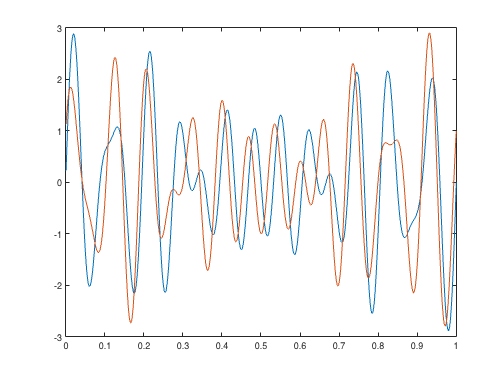

plot(time, testsig_sines), 
hold on 
plot(time, testsig_sincos)

First, the regular discrete Fourier transform on the each data segment, resulting in complex spectra with real and imag components

fft1 = fft(testsig_sines);
fft2 = fft(testsig_sincos);

and now, we do the dot product of integer sines and cosines and the test signals. 

for x = 1:30; sindot1(x) = testsig_sines*sin(time*2*pi*x)'; end
for x = 1:30; sindot2(x) = testsig_sincos*sin(time*2*pi*x)'; end
for x = 1:30; cosdot1(x) = testsig_sines*cos(time*2*pi*x)'; end
for x = 1:30; cosdot2(x) = testsig_sincos*cos(time*2*pi*x)'; end

Plot the resulting spectra

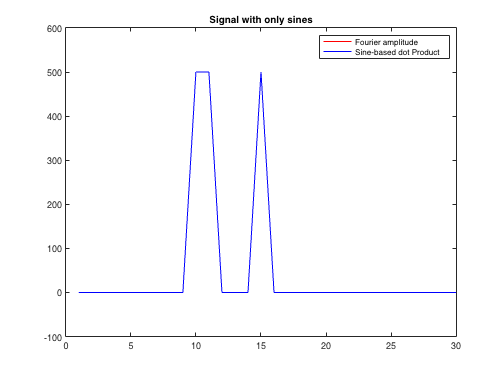

figure
plot(1:30, abs(fft1(2:31)), 'r')
hold on
plot(1:30, sindot1(1:30), 'b')
title('Signal with only sines')
legend('Fourier amplitude', 'Sine-based dot Product')

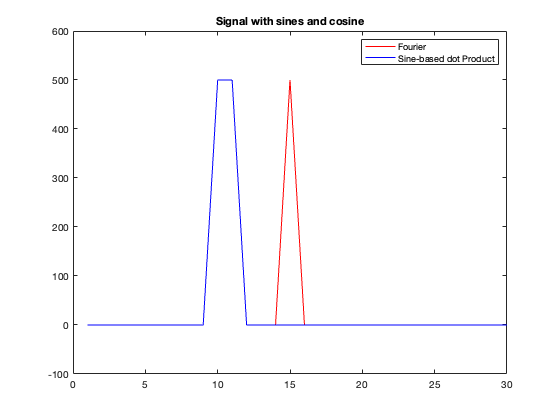


figure
plot(1:30, abs(fft2(2:31)), 'r')
hold on
plot(1:30, sindot2(1:30), 'b')
title('Signal with sines and cosine')
legend('Fourier', 'Sine-based dot Product')

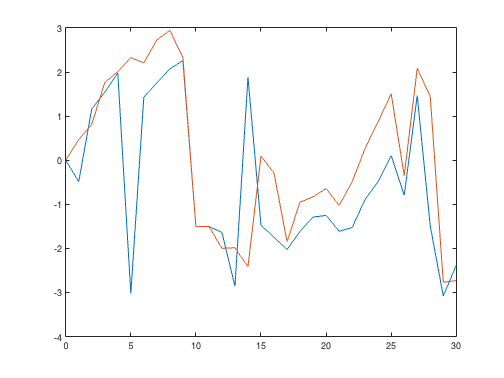

figure
plot(0:30, angle(fft1(1:31)))
hold on
plot(0:30, angle(fft2(1:31)))